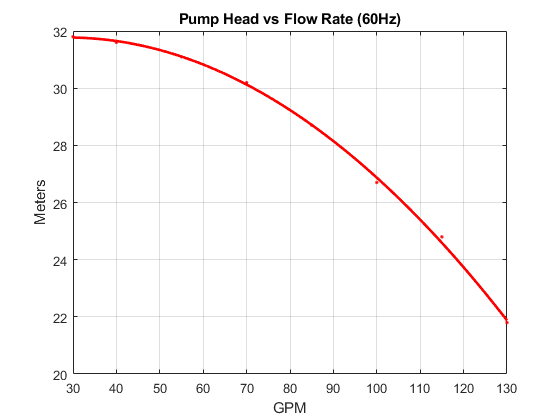

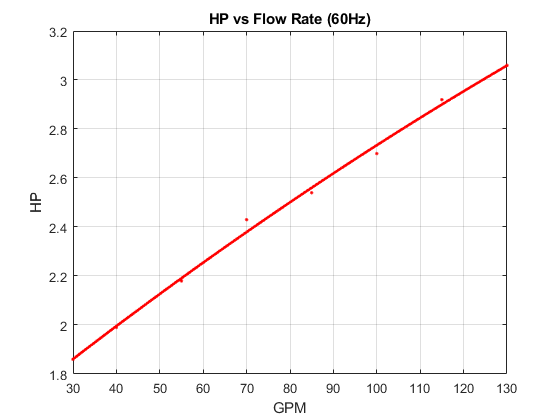

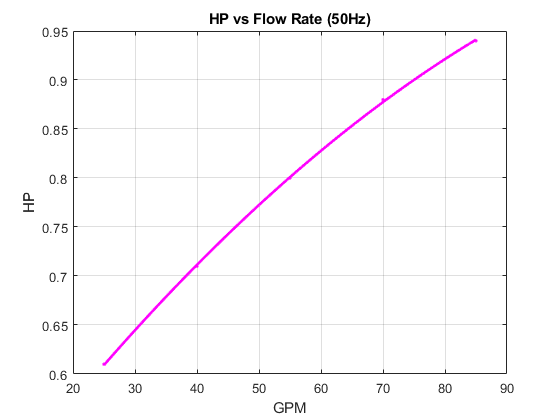

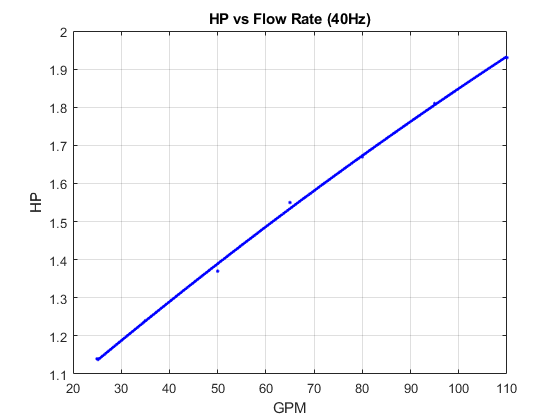

clear;cla;clf;clc
M = csvread('ENGR302LAB7CSV.csv');
head = 11;
eff = 16;
HP = 15;

Q = 2;

Hz6 = 1:8;
Hz4 = 9:15;
Hz5 = 16:20;

Freq = {Hz6; Hz5; Hz4};
Pram = {head, eff, HP};
charTitle = {'Pump Head', 'Efficiency', 'HP'};
FreqT = {'(60Hz)', '(50Hz)', '(40Hz)'};
xUnit = 'GPM';
yUnit = {'Meters', 'Efficiency', 'HP'};
color = ['r','m','b'];



for I = 1:1:3
    for N = 1:1:3
        f = fit(M(Freq{N}(:), Q), M(Freq{N}(:), Pram{I}(:)), 'poly2');
        figure(N);
        currentFig = plot(f,M(Freq{N}(:), Q), M(Freq{N}(:), Pram{I}(:)));
        set(currentFig, 'color', color(N));
        set(currentFig, 'LineWidth',2)
        title([charTitle{I}, ' vs Flow Rate ', FreqT{N}]);
        grid on;
        legend('off')
        xlabel(xUnit)
        ylabel(yUnit{I})
        saveas(figure(N),['ENGR302LAB7FIG',yUnit{I},FreqT{N}], 'jpg')
        saveas(figure(N),['ENGR302LAB7FIG',yUnit{I},FreqT{N}], 'pdf')
    end
end